clc
clear
disp("Initilization Procedure")

Initilization Procedure


model.Parameters
param = control.calculateOperatingPoint(param);

Calculate Operating Point for T_a = 293.150000 [K]

param = model.calculateModel(param);

Calculate bilinear model matrices
Calculate linearisation decoupled
Calculate linearisation coupled
Testing controlability
Testing T_ref


param = model.calculateWDelta(param,0);

listOfUncertainties = {[-1,1]};
% Generates a diagonal matrix for each vertex given the uncertainties.
% Firstly every combination of uncertainties is generated, then
% structured into a 3D array of diagonal matrices.
m = length(listOfUncertainties);
Uncertainties = zeros(m,m,m^2);
if(m == 1)% check if the inputs share uncertainties or if they have individual uncertainties
    comb = combinations(cell2mat(listOfUncertainties(1)));
else
    comb = combinations(cell2mat(listOfUncertainties(1)),cell2mat(listOfUncertainties(2)),cell2mat(listOfUncertainties(3)),cell2mat(listOfUncertainties(4)));
end
combDouble = table2array(comb);
for i=1:length(combDouble)
    Uncertainties(:,:,i) = diag(combDouble(i,:));
end

B = @(i) param.model.B*(eye(4) + Uncertainties(i) * param.model.Dwd);
Q = eye(20);
tol = 1e-2;
tol_alpha = 0.005;
n = param.n;
yalmip('clear')
gamma = sdpvar(1);
A_1 = [param.model.A, param.model.Bw*param.model.Cww, zeros(12,4);
        zeros(4,12), param.model.Aww, zeros(4,4);
        param.model.Bwz*param.model.Cz, -param.model.Bwz*param.model.Cww, param.model.Awz];
B_1 = @(k) [B(k); zeros(4,4); zeros(4,4)];
C_1 = [param.model.CySOF, zeros(8,4), zeros(8,4)];
B_CL = [param.model.Bw*param.model.Dww; param.model.Bww; -param.model.Bwz*param.model.Dww];
C_CL = [param.model.Dwz*param.model.Cz, -param.model.Dwz*param.model.Cww, param.model.Cwz];
D_CL = [-param.model.Dwz*param.model.Dww];
A_bar = [A_1, B_CL, zeros(20,4);
        zeros(4,20), -gamma/2*eye(4), zeros(4,4);
        C_CL, D_CL, -gamma/2*eye(4)];
B_bar = @(k) [B_1(k); zeros(4,4); zeros(4,4)];
C_bar = [C_1, zeros(8,4), zeros(8,4)];


% Step 1
% [P_bar, ~, P] = constructVariables(param);
% p = cell(1,param.n);
% for i=1:param.n
%     p{i} = sdpvar(3);
% end
% P = sdpvar(20);
% P(1:12,1:12) = blkdiag(p{1:end})
% constraints = [];
% for k=1:length(Uncertainties)
%     constraints = [constraints, [A_1.' * P + P * A_1 + Q, P * B_1(k); B_1(k).' * P, eye(n)] >= 0];
% end
% constraints = [constraints, P >= 0];
% options = sdpsettings('verbose',0,'solver','mosek');
% sol = optimize(constraints, -trace(P), options)
yalmip('clear')
q = cell(1,param.n);
y = cell(1,param.n);
for i=1:param.n
    q{i} = sdpvar(3);
    y{i} = sdpvar(1,3,'full');
end
Q = blkdiag(q{:});
Y = blkdiag(y{:});

% Setup constraint
constraints = [param.model.A * Q + Q * param.model.A.' + param.model.B_Bar * Y + Y.' * param.model.B_Bar.' <=0];
for i=1:length(Uncertainties)
    constraints = [constraints, param.model.A * Q + Q * param.model.A.' + param.model.B * (eye(4) + Uncertainties(i) * param.model.Dwd) * Y + Y.' * (eye(4) + Uncertainties(i) * param.model.Dwd)' * param.model.B.' <= 0];
end
% constraints = [constraints,  Q - eye(12) >= 0];
% options = sdpsettings('verbose',0,'solver','mosek');
% sol = optimize(constraints, trace(Q), options)
constraints = [constraints,  Q >= 0];
options = sdpsettings('verbose',0,'solver','mosek');
sol = optimize(constraints, [], options);


value(Q)

ans =     0.6589    0.3702   -0.6175         0         0         0         0         0         0         0         0         0
    0.3702    0.4316   -0.3591         0         0         0         0         0         0         0         0         0
   -0.6175   -0.3591    1.6354         0         0         0         0         0         0         0         0         0
         0         0         0    0.6564    0.3705   -0.6167         0         0         0         0         0         0
         0         0         0    0.3705    0.4305   -0.3594         0         0         0         0         0         0
         0         0         0   -0.6167   -0.3594    1.6343         0         0         0         0         0         0
         0         0         0         0         0         0    0.6566    0.3696   -0.6176         0         0         0
         0         0         0         0         0         0    0.3696    0.4312   -0.3592         0         0         0
         0         0      

X(:,:,1) = blkdiag(inv(value(Q)),eye(16))

X =     3.7076   -2.4662    0.8584         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -2.4662    4.4754    0.0515         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.8584    0.0515    0.9469         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0    3.7496   -2.5059    0.8638         0         0         0         0         0         0         0         0         0   

i = 1;

while 1
    % Step 2
    yalmip('clear')
    [P_bar, Ksof] = constructVariables(param);
    gamma = sdpvar(1);
     A_bar = [A_1, B_CL, zeros(20,4);zeros(4,20), -gamma/2*eye(4), zeros(4,4);C_CL, D_CL, -gamma/2*eye(4)];
    
    alpha = sdpvar(1);
    constraints = [];
    for k=1:length(Uncertainties)
        constraints = [constraints, [A_bar.'*P_bar + P_bar*A_bar - X(:,:,i)*(B_bar(k)*B_bar(k).')*P_bar - P_bar*(B_bar(k)*B_bar(k).')*X(:,:,i) + X(:,:,i)*(B_bar(k)*B_bar(k).')*X(:,:,i) - alpha*P_bar , (B_bar(k).'*P_bar + Ksof*C_bar).';
                        (B_bar(k).'*P_bar + Ksof*C_bar), -eye(n)] <= 0];
    end
    constraints = [constraints, P_bar >= 0];
    options = sdpsettings('verbose',0,'solver','mosek');
    sol = bisection(constraints, alpha, options);
    alpha_min = value(alpha)
    % Step 3
    if(alpha_min <= tol_alpha)
        break
    end
    % Step 4
    yalmip('clear')
    [P_bar, Ksof] = constructVariables(param);
    gamma = sdpvar(1);
    A_bar = [A_1, B_CL, zeros(20,4);zeros(4,20), -gamma/2*eye(4), zeros(4,4);C_CL, D_CL, -gamma/2*eye(4)];
    constraints = [];
    for k=1:length(Uncertainties)
        constraints = [constraints, [A_bar.'*P_bar + P_bar*A_bar - X(:,:,i)*(B_bar(k)*B_bar(k).')*P_bar - P_bar*(B_bar(k)*B_bar(k).')*X(:,:,i) + X(:,:,i)*(B_bar(k)*B_bar(k).')*X(:,:,i) - alpha_min*P_bar , (B_bar(k).'*P_bar + Ksof*C_bar).';
                        (B_bar(k).'*P_bar + Ksof*C_bar), -eye(n)] <= 0];
    end
    constraints = [constraints, P_bar >= 0];
    options = sdpsettings('verbose',0,'solver','mosek');
    sol = optimize(constraints, trace(P_bar), options);
    P_min(:,:,i) = value(P_bar);
    % Step 5
    if (norm(X(:,:,i) - P_min(:,:,i)) < tol)
        % Step 6
        break
    else
        i = i + 1;
        X(:,:,i) = P_min(:,:,i-1);
    end
end

alpha_min = 0.1283

alpha_min = -0.1016


Ksof = value(Ksof);
Ks = zeros(1,3,param.n);
for j=1:param.n
    Ks(1,2:3,j) = Ksof(j,2*(j-1)+1:2*j);
end

% Evaluation of the results from the design procedure
fprintf("Evaluation of design procedure for ILMI SOF \n")

Evaluation of design procedure for ILMI SOF 


fprintf("Gamma is found to be: %f \n", value(gamma))

Gamma is found to be: 248894.658351 


if(eig(param.model.A+param.model.B_Bar*Ksof*param.model.CySOF) > 0)
    fprintf("One or more eigenvalues in the decoupled system is positive!!! \n")
else
    fprintf("Eigenvalues of the decoupled systems are all negative \n")
end

Eigenvalues of the decoupled systems are all negative 


eig(param.model.A+param.model.B_Bar*Ksof*param.model.CySOF).'

ans =    -3.6613   -0.3031   -0.0726   -3.6966   -0.2957   -0.0831   -3.6491   -0.2845   -0.1034   -3.6573   -0.2919   -0.0877



if(eig(param.model.A+param.model.B*Ksof*param.model.CySOF) > 0)
    fprintf("One or more eigenvalues in the coupled system is positive!!! \n")
else
    fprintf("Eigenvalues of the coupled systems are all negative \n")
end

Eigenvalues of the coupled systems are all negative 


eig(param.model.A+param.model.B*Ksof*param.model.CySOF).'

ans =    -3.3486   -3.0975   -3.0489   -2.9546   -0.6190   -0.8688   -0.9426   -0.9988   -0.0882   -0.0668   -0.0780   -0.0744


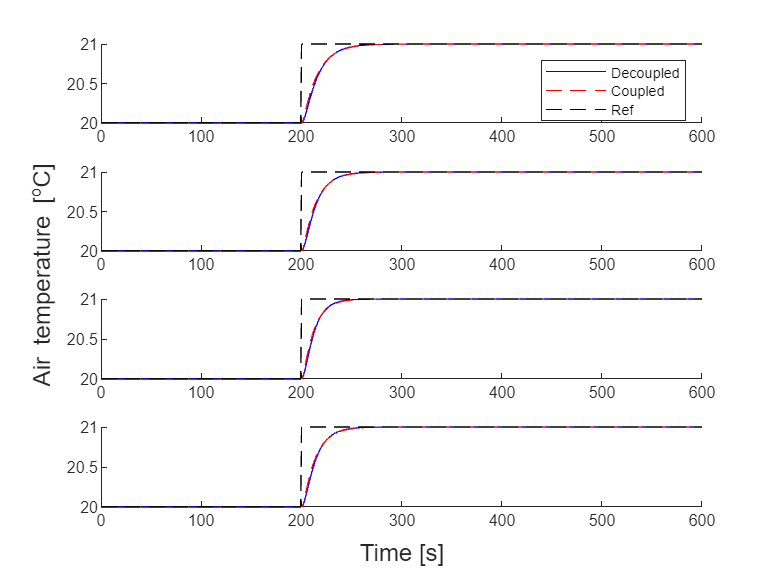

%saves the block version of K this is used further in some simulations
param.ctrl.K = Ksof*param.model.CySOF;
%saves a 3d matrix version of Ks this is used in the simulation of the
%nonlinear system.
param.ctrl.Ks = Ks;


util.SimulateLinearStep(param,"Examination_Output_Feedback_ILMI_Hinf",0);

function [P_bar, Ksof, P] = constructVariables(param)
    ksof = cell(1,param.n);
    p = cell(1,param.n);
    for i=1:param.n
        p{i} = sdpvar(3);
        ksof{i} = sdpvar(1,2,'full');
    end
    P = sdpvar(20);
    P(1:12,1:12) = blkdiag(p{1:end});
    P_bar = blkdiag(P,eye(4),eye(4));
    Ksof = blkdiag(ksof{:});
end